## MATLABthon @Polimi 2023

The goal of this project is to estimate the stride of a person and its evolution through time.

Load the data of the chosen person and plot it. Change the name of the file depending on the person being analyzed.

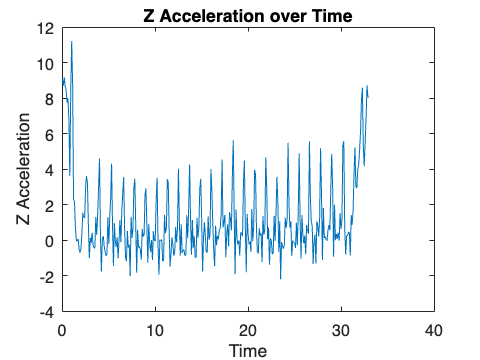

person = load("walking_data/Person1.mat");

t = timeElapsed(person.Acceleration.Timestamp);
acc_z= person.Acceleration.Z;

figure
plot(t,acc_z)
xlabel('Time')
ylabel('Z Acceleration')
title('Z Acceleration over Time')

Find the peaks and plot them. Each peach is a movement of a leg, so to get the number of steps we multiply by 2.

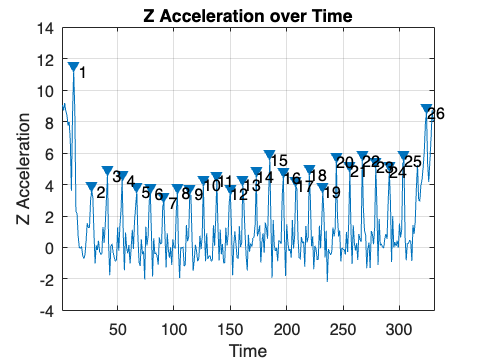

figure

[peaks, peakLocations] = findpeaks(acc_z, 'MinPeakProminence', 3);

findpeaks(acc_z, 'MinPeakProminence', 3);

text(peakLocations+.02,peaks,num2str((1:numel(peaks))'))
xlabel('Time')
ylabel('Z Acceleration')
title('Z Acceleration over Time')


num_passi = 2*length(peaks);

disp(['The total number of steps is: ', num2str(num_passi)])

The total number of steps is: 52


Now we compute the total distance walked by the person and plot the cumulative distance over time.

earthCirc = 24901;

lat = person.Position.latitude;
lon = person.Position.longitude;
positionDatetime = person.Position.Timestamp;

totaldis = 0;
dis = [];

for i = 1:(length(lat)-1)
    lat1 = lat(i);     % The first latitude
    lat2 = lat(i+1);   % The second latitude
    lon1 = lon(i);     % The first longitude
    lon2 = lon(i+1);   % The second longitude

    degDis = distance(lat1, lon1, lat2, lon2);

    dis = [dis;(degDis/360)*earthCirc*1609.34];

    totaldis = totaldis + (degDis/360)*earthCirc;
end

totaldis_ft = totaldis*5280;    % Converting distance from miles to feet
totaldis_mt=totaldis*1609.34;    % Converting distance from miles to meters

disp(['The total distance traveled is: ', num2str(totaldis),' miles'])

The total distance traveled is: 0.01759 miles


disp(['The total distance traveled is: ', num2str(totaldis_ft),' feet'])

The total distance traveled is: 92.8752 feet


disp(['The total distance traveled is: ', num2str(totaldis_mt),' meters'])

The total distance traveled is: 28.3083 meters


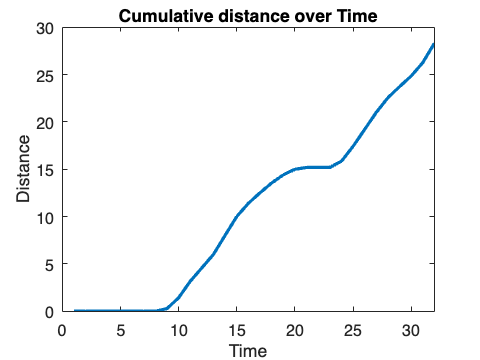


dis_new(1) = 0.75*dis(1)+0.25*dis(2);  % Distance overlap for homogeneity

for i=2:length(dis)-1
    dis_new(i)= 0.5*dis(i)+ 0.25*dis(i-1) + 0.25*dis(i+1);
end

dis_new(length(dis)) = 0.75*dis(length(dis))+0.25*dis(length(dis)-1);

cum_dis= zeros(length(dis),1);  % Vector of cumulative distance

for i=1:length(dis)
    cum_dis(i) = sum(dis_new(1:i));
end

figure
plot(cum_dis, 'LineWidth', 2)
xlabel('Time')
ylabel('Distance')
title('Cumulative distance over Time')

We can now compute the mean stride over time.

mean_stride = totaldis_mt/num_passi;

disp(['The mean length of the stride is: ', num2str(mean_stride),' meters'])

The mean length of the stride is: 0.54439 meters


Now implement a sliding window approach to compute the stride at every window and get an estimate of the evolution of the stride over time. Then we interpolate and plot.

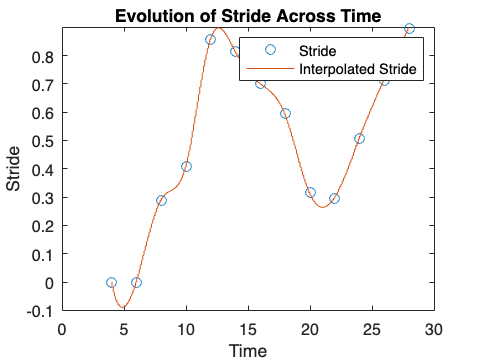

dt = t(2)-t(1);

% Parameters for the sliding window
windowSize_sec = 8;  % Window length 10s
windowSize_pts = int64(windowSize_sec/dt);
windowStep_sec = 2;  % Window movement step 5s
windowStep_pts = int64(windowStep_sec/dt);

% Initialize variables
numWindows = floor((length(acc_z) - windowSize_pts) / windowStep_pts);
strideValues = zeros(numWindows, 1);
midPoints = zeros(numWindows, 1);

temp = [];
time = 0;
for i = 1:length(person.Position.Timestamp)
    for k = 1:10
        temp = [temp; person.Position.longitude(i)];
        time = time + 0.1;
    end
end
lon_repeated = temp;

temp = [];
time = 0;
for i = 1:length(person.Position.Timestamp)
    for k = 1:10
        temp = [temp; person.Position.latitude(i)];
        time = time + 0.1;
    end
end

lat_repeated = temp;

% Sliding window approach
for i = 1:numWindows
    windowStart = (i - 1) * windowStep_pts + 1;
    windowEnd = windowStart + windowSize_pts - 1;
    windowData = acc_z(windowStart:windowEnd);
 
    % Compute stride for the current window
    numSteps = 2*numel(findpeaks(windowData, 'MinPeakProminence', 3));
    %dist = trapz(windowData);

    lat_win = lat_repeated(windowStart:windowEnd);
    lon_win = lon_repeated(windowStart:windowEnd);

    the_dist = compute_distance(lat_win, lon_win);

    stride = the_dist / numSteps;
    
    % Store stride and mid point of the window
    strideValues(i) = stride;
    midPoints(i) = (windowStart + windowEnd) / 2;
end

% Interpolate the stride values
interpMidPoints = min(midPoints):0.1:max(midPoints);
interpStrideValues = interp1(midPoints, strideValues, interpMidPoints, 'spline');

% Plot the evolution of stride across time
i1 = floor(midPoints);
i2 = floor(interpMidPoints);
plot(t(i1), strideValues, 'o', t(i2), interpStrideValues, '-');
xlabel('Time');
ylabel('Stride');
title('Evolution of Stride Across Time');
legend('Stride', 'Interpolated Stride');